## **Modeling and Control of CyberPhysical Systems - Control **

### **Control part - Task 1**

#### *No noise*

s = tf('s');
H=7 %%minimum H for clean case

H = 7

%transfer function. Used only to generate outputs
G = 100 / (s^2 + 1.2*s + 1);
G_discrete = c2d(G,1,'zoh')

G_discrete =
 
      32.24 z + 21.41
  -----------------------
  z^2 - 0.7647 z + 0.3012
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


[num,den] = tfdata(G_discrete, 'v')

num =          0   32.2369   21.4103


den =     1.0000   -0.7647    0.3012


theta_real = [den(2:end) num] %%2: in order to exclude z^2 coefficient

theta_real =    -0.7647    0.3012         0   32.2369   21.4103


%%calculating output
u = rand(H,1);
y = lsim(G_discrete,u);
%%building A 
A = [-y(2:H-1) -y(1:H-2) u(3:H) u(2:H-1) u(1:H-2)];

theta_real

theta_real =    -0.7647    0.3012         0   32.2369   21.4103


theta = inv(A)*y(3:end)

theta =    -0.7647
    0.3012
    0.0000
   32.2369
   21.4103


*Noise dependent from the denominator*

H_vector = 7:20:100000;
theta_real_values = [];
theta_estimated_values = [];

% simulation for H from 7 to 100,000
for i = 1:length(H_vector)

    u = rand(H_vector(i),1);
    e = 5 * randn(H_vector(i),1);
    y_noise_dep = lsim(G_discrete,u) + lsim(tf(1,den,1),e);
    A = [-y_noise_dep(2:H_vector(i)-1) -y_noise_dep(1:H_vector(i)-2) u(3:H_vector(i)) u(2:H_vector(i)-1) u(1:H_vector(i)-2)];
    
    theta_real;
    theta_estimated = (pinv(A)*y_noise_dep(3:end))';
    
    theta_real_values = [theta_real_values, theta_real];
    theta_estimated_values = [theta_estimated_values, theta_estimated];
end

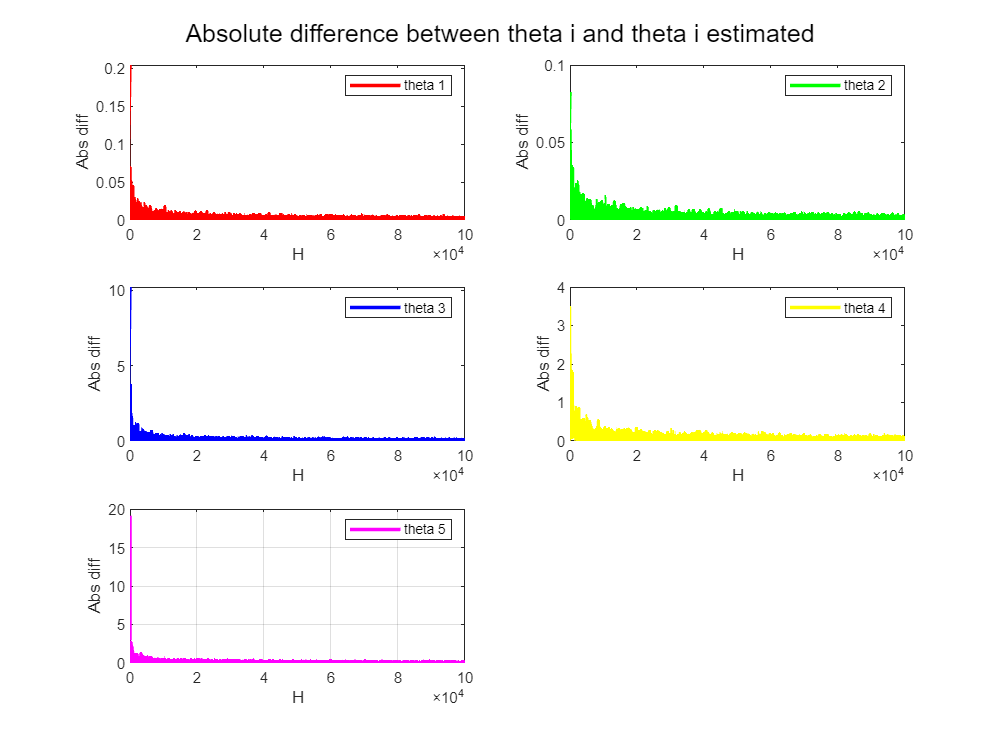

% Plotting absolute difference of theta and theta estimated
figure_width = 800; % Width in pixels
figure_height = 600; % Height in pixels
figure('Position', [100, 100, figure_width, figure_height]);

subplot(3, 2, 1);
plot(H_vector, abs(theta_estimated_values(1:5:end) - theta_real_values(1:5:end)), 'r', 'LineWidth', 2);
xlabel('H');
ylabel('Abs diff');
legend('theta 1');

subplot(3, 2, 2);
plot(H_vector, abs(theta_estimated_values(2:5:end) - theta_real_values(2:5:end)), 'g', 'LineWidth', 2);
xlabel('H');
ylabel('Abs diff');
legend('theta 2');

subplot(3, 2, 3);
plot(H_vector, abs(theta_estimated_values(3:5:end) - theta_real_values(3:5:end)), 'b', 'LineWidth', 2);
xlabel('H');
ylabel('Abs diff');
legend('theta 3');

subplot(3, 2, 4);
plot(H_vector, abs(theta_estimated_values(4:5:end) - theta_real_values(4:5:end)), 'y', 'LineWidth', 2);
xlabel('H');
ylabel('Abs diff');
legend('theta 4');

subplot(3, 2, 5);
plot(H_vector, abs(theta_estimated_values(5:5:end) - theta_real_values(5:5:end)), 'magenta', 'LineWidth', 2);
xlabel('H');
ylabel('Abs diff');
legend('theta 5');

sgtitle('Absolute difference between theta i and theta i estimated');
grid on;

*Real scenario - OUTPUT ERROR*

H_vector = 7:20:100000;
theta_real_values = [];
theta_estimated_values_oe = [];

% simulation for H from 7 to 100,000
for i = 1:length(H_vector)

    u = rand(H_vector(i),1);
    e = 5 * randn(H_vector(i),1);
    y_noise_oe = lsim(G_discrete,u) + e;
    A_oe = [-y_noise_oe(2:H_vector(i)-1) -y_noise_oe(1:H_vector(i)-2) u(3:H_vector(i)) u(2:H_vector(i)-1) u(1:H_vector(i)-2)];
    
    theta_estimated_oe = (pinv(A_oe)*y_noise_oe(3:end))';
    
    theta_real_values = [theta_real_values, theta_real];
    theta_estimated_values_oe = [theta_estimated_values_oe, theta_estimated_oe];
end

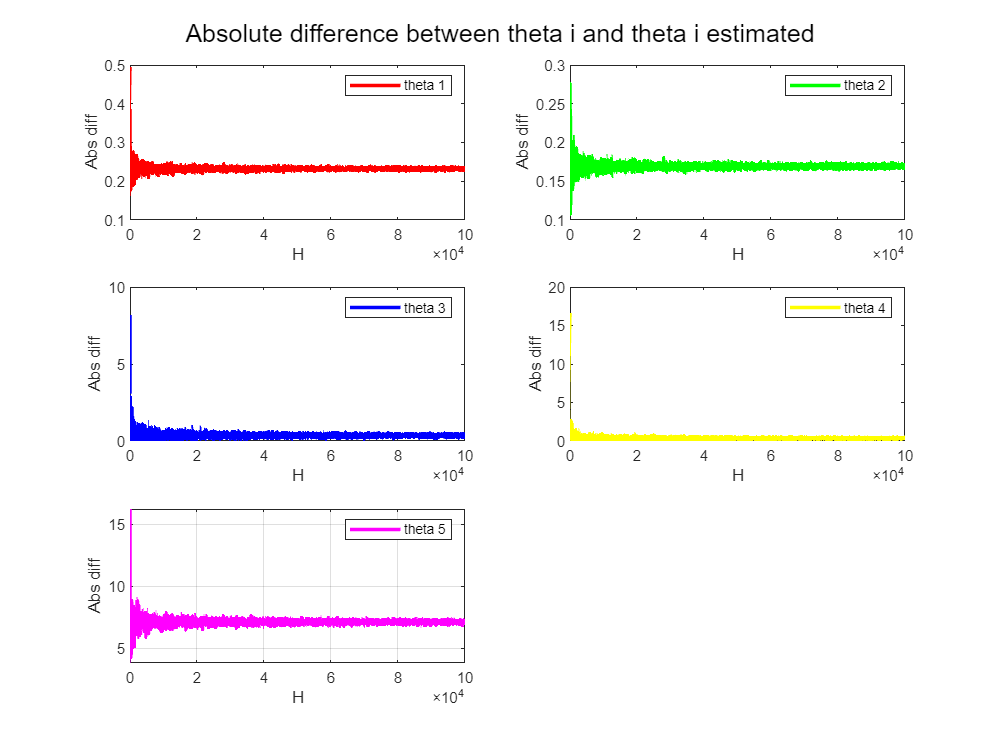

% Plotting absolute difference of theta and theta estimated
figure_width = 800; % Width in pixels
figure_height = 600; % Height in pixels
figure('Position', [100, 100, figure_width, figure_height]);

subplot(3, 2, 1);
plot(H_vector, abs(theta_estimated_values_oe(1:5:end) - theta_real_values(1:5:end)), 'r', 'LineWidth', 2);
xlabel('H');
ylabel('Abs diff');
legend('theta 1');

subplot(3, 2, 2);
plot(H_vector, abs(theta_estimated_values_oe(2:5:end) - theta_real_values(2:5:end)), 'g', 'LineWidth', 2);
xlabel('H');
ylabel('Abs diff');
legend('theta 2');

subplot(3, 2, 3);
plot(H_vector, abs(theta_estimated_values_oe(3:5:end) - theta_real_values(3:5:end)), 'b', 'LineWidth', 2);
xlabel('H');
ylabel('Abs diff');
legend('theta 3');

subplot(3, 2, 4);
plot(H_vector, abs(theta_estimated_values_oe(4:5:end) - theta_real_values(4:5:end)), 'y', 'LineWidth', 2);
xlabel('H');
ylabel('Abs diff');
legend('theta 4');

subplot(3, 2, 5);
plot(H_vector, abs(theta_estimated_values_oe(5:5:end) - theta_real_values(5:5:end)), 'magenta', 'LineWidth', 2);
xlabel('H');
ylabel('Abs diff');
legend('theta 5');

sgtitle('Absolute difference between theta i and theta i estimated');
grid on;